# Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 5. Modelo COVID-19

Se sigue el artículo [I. Ahmed et al. A mathematical model of Coronavirus Disease (COVID-19) containing asymptomatic and symptomatic classes. Results in Physics. Volume 21, 2021, 103776. 2020](https://www.sciencedirect.com/science/article/pii/S2211379720321860?via%3Dihub).

### Notación

Para cada instante de tiempo $t$, la población total, $N(t)$, se compone de individuos

- susceptibles de infectarse, $S(t)$,

- ya expuestos al virus en dicho instante , $E(t)$,

- ya infectados y asintomáticos, $I_A(t)$,

- ya infectados y sintomáticos, $I_S(t)$,

- en cuarentena, $Q(t)$,

- recuperados o fallecidos, $R(t)$.

Para la evolución de las variables anteriores consideramos los parámetros:

- tasa de natalidad por unidad de tiempo, $\Lambda$,

- tasa de mortalidad natural, $\mu$,

- tasa de mortalidad entre sintomáticos, $\delta$ (suponemos nula la mortalidad entre asintomáticos),

- porcentaje de recuperados de entre los asintomáticos por unidad de tiempo, $r_1$ (resp. sintomáticos, $r_2$),

- porcentaje de susceptibles que van a cuarentena, $\tau$,

- porcentaje de contactos entre susceptibles y expuestos, i.e., *ratio de transmisión o de contacto efectivo*, $\beta$,

- porcentaje de expuestos que van a cuarentena, $\gamma$,

- porcentaje de expuestos que pasan a infectados sintomáticos, $\eta$ (resp. asintomáticos, $\sigma$),

- porcentaje de individuos en cuarentena que pasan a infectados sintomáticos, $\upsilon$ (resp. asintomáticos, $\theta$),

Los procesos de transmisión se resumen en la Figura 2.2 del artículo.

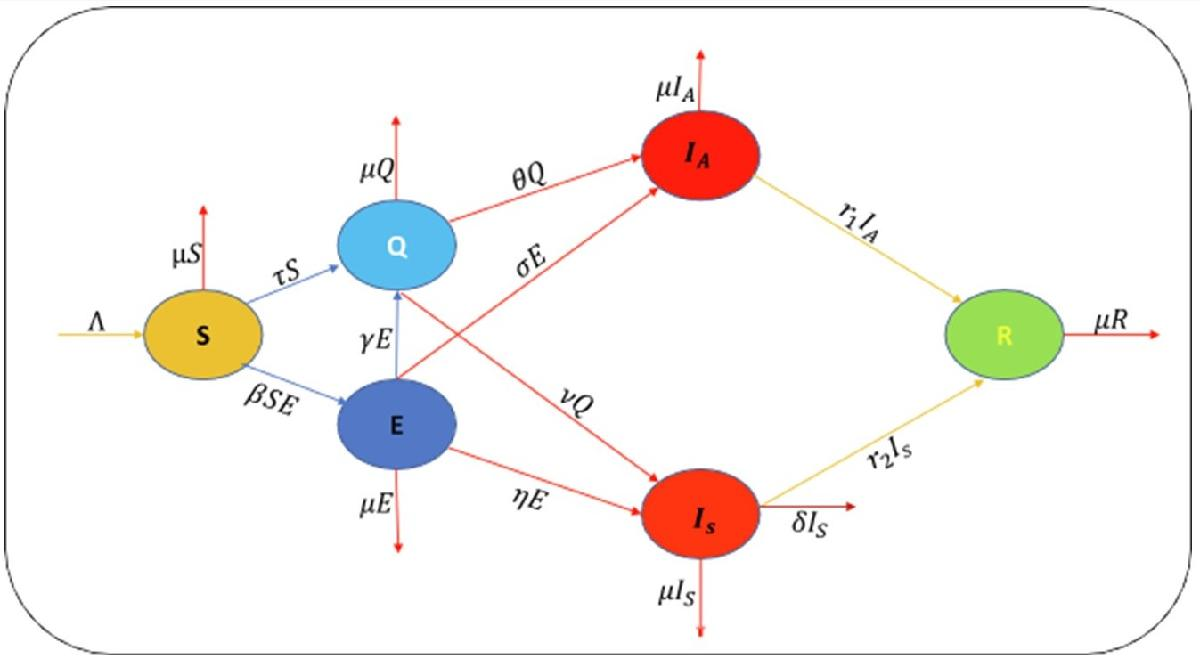

### Modelo determinista

El sistema de EDO, para $t>0$, es el siguiente:


$$\frac{\mathrm{d}S(t)}{\mathrm{d}t}=\Lambda -(\tau+\mu)S(t)-\beta S(t) E(t),$$



$$\frac{\mathrm{d}E(t)}{\mathrm{d}t}=\beta S(t) E(t)- (\gamma +\mu+\eta +\sigma)E(t),$$



$$\frac{\mathrm{d}Q(t)}{\mathrm{d}t}=\tau S(t) +\gamma E(t) - (\mu+\upsilon +\theta)Q(t),$$



$$\frac{\mathrm{d}I_A(t)}{\mathrm{d}t}=\sigma E(t) +\theta Q(t) -(\mu+r_1)I_A(t),$$



$$\frac{\mathrm{d}I_S(t)}{\mathrm{d}t}=\eta E(t) +\upsilon Q(t) -(\delta+\mu+r_2)I_S(t),$$


$\frac{\mathrm{d}R(t)}{\mathrm{d}t}=r_1I_A(t)+r_2I_S(t)-\mu R(t)$.

Además se precisan condiciones iniciales para $S$, $E$, $Q$, $I_A$, $I_S$ y $R$.

### Interpretación

El modelo presentado es adimensional. Si $\Lambda$ es la tasa de natalidad por habitante, entonces $\Lambda^*= k\Lambda$ es la tasa para $k$ habitantes. El sistema se entiende referido a $k$ habitantes, de forma que:

$S^*(t) = kS(t)$, $E^*(t) = kE(t)$, $Q^*(t) = kQ(t)$, $I_A^*(t) = kI_A(t)$, $I_S^*(t) = kI_S(t)$ y $R^*(t) = kR(t)
$

El sistema de EDO sigue siendo válido, cambiando la tasa $\beta$  por $\beta^*=\beta/k$.

El *número básico de reproducción* se define como el valor esperado del porcentaje de infectados secundarios por cada infectado activo por

unidad de tiempo:

$\mathcal{R}_0=\frac{\beta \Lambda}{(\gamma+\mu+\eta+\sigma)(\tau+\mu)}$. 

Si $\mathcal{R}_0<1$, la enfermedad dismuirá. Como $\beta\Lambda = \beta^*\Lambda^*=\mathrm{cte.}$, el número básico de reproducción es independiente de la población considerada.

Finalmente,

- $1/r_1$ es el tiempo que tarda un asintomático en recuperarse,

- $1/r_2$ es el tiempo que tarda un sintomático en recuperarse,

- $1/(\eta+\sigma)$ es el tiempo de incubación de la enfermedad, en ausencia de cuarentena.

### Ejercicio 5.1. 

Considera el sistema de EDO del artículo, con condiciones iniciales $(S_0,E_0,Q_0,I_{A0}, I_{S0}, R_0) = (0.5, 0.2, 0.1, 0.2, 0.1, 0)$ y los parámetros 

$\tau= 0.0002$, $\beta=0.0805$, $\delta= 1.6728e-5$, $\gamma = 2.0138e-4$, $\eta=0.4478$, $\theta=0.0101$, $\mu=0.0106$, $\upsilon=3.2084e-4$, $\sigma=0.0668$, $\Lambda=0.02537/365$, $r_1=5.7341e-5$ y $r_2=1.6728e-5$, medidos en días$^{-1}$. 

[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 0.2, 0.1, 0.2, 0.1, 0)

S0 = 0.5000

E0 = 0.2000

Q0 = 0.1000

IA0 = 0.2000

IS0 = 0.1000

R0 = 0


P  = struct('tau', 0.0002, 'beta', 0.0805, 'delta', 1.6728e-5, 'gamma', 2.0138e-4, ...
    'eta', 0.4478, 'tita', 0.0101, 'mu', 0.0106, 'nu', 3.2084e-4, 'sigma', 0.0668, ...
    'Lambda', 0.02537, 'r1', 5.7341e-5, 'r2', 1.6728e-5)

P = struct with fields:
       tau: 2.0000e-04
      beta: 0.0805
     delta: 1.6728e-05
     gamma: 2.0138e-04
       eta: 0.4478
      tita: 0.0101
        mu: 0.0106
        nu: 3.2084e-04
     sigma: 0.0668
    Lambda: 0.0254
        r1: 5.7341e-05
        r2: 1.6728e-05


Q = P;

- **Calcula la población inicial y el número básico de reproducción.**

N0 = sum([S0, E0, Q0, IA0, IS0, R0]);
disp(['Poblacion inicial: ' num2str(N0) ' individuos.'])

Poblacion inicial: 1.1 individuos.


R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


- **Calcula los días que tardan los infectados sintomáticos y asintomáticos en recuperarse, así como los días de incubación.**

disp(['Dias para la recuperacion de un asintomatico: ' num2str(1/P.r1)])

Dias para la recuperacion de un asintomatico: 17439.5284


disp(['Dias para la recuperacion de un  sintomatico: ' num2str(1/P.r2)])

Dias para la recuperacion de un  sintomatico: 59780.0096


disp(['Dias previstos para incubacion: ' num2str(1/(P.nu+P.sigma))])

Dias previstos para incubacion: 14.8985


- **Calcula la tasa de natalidad anual por cada mil individuos.**

El resultado permitirá observar que la tasa de natalidad dada en el artículo tiene unidades por año y no por día. Como ejemplo, la tasa de natalidad de Nigeria en 2018 fue de el 3,791%, es decir 38 nacimientos por cada 1000 habitantes, mientras que la tasa de España ese año fue del 0,794%.

disp(['Tasa de natalidad anual por mil habitantes (incorrecta si Lambda se mide en dias^-1): ' num2str(1000*365*P.Lambda)])

Tasa de natalidad anual por mil habitantes (incorrecta si Lambda se mide en dias^-1): 9260.05


disp(['Tasa de natalidad anual por mil habitantes: ' num2str(1000*P.Lambda)])

Tasa de natalidad anual por mil habitantes: 25.37


Como consecuencia de lo anterior, se corrige el valor de $\Lambda$.

P.Lambda = P.Lambda/365

P = struct with fields:
       tau: 2.0000e-04
      beta: 0.0805
     delta: 1.6728e-05
     gamma: 2.0138e-04
       eta: 0.4478
      tita: 0.0101
        mu: 0.0106
        nu: 3.2084e-04
     sigma: 0.0668
    Lambda: 6.9507e-05
        r1: 5.7341e-05
        r2: 1.6728e-05


- **Calcula la tasa de mortalidad anual por cada mil individuos.**

Compara el resultado con las tasas obtenidas en Nigeria para el año 2018.

disp(['Tasa de mortalidad anual por mil habitantes: ' num2str(P.mu*1000)])

Tasa de mortalidad anual por mil habitantes: 10.6


- **Reproduce la Figura 5.5 del artículo.**

Utiliza el comando [ode45](https://es.mathworks.com/help/matlab/ref/ode45.html?searchHighlight=ode45&s_tid=srchtitle_ode45_1) para resolver el sistema de EDO. Observa que, aunque la figura indica que el resultado corresponde a 100 semanas, realmente se consideran 100 días en el eje $x$. Además, al reducir la tasa de natalidad, $S(t)$ será decreciente. 

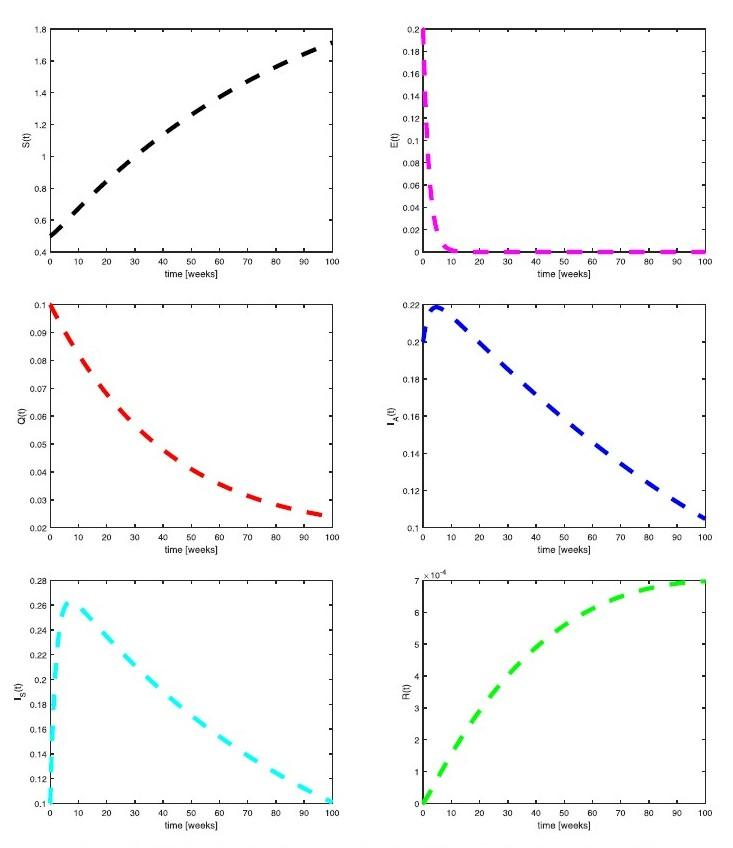

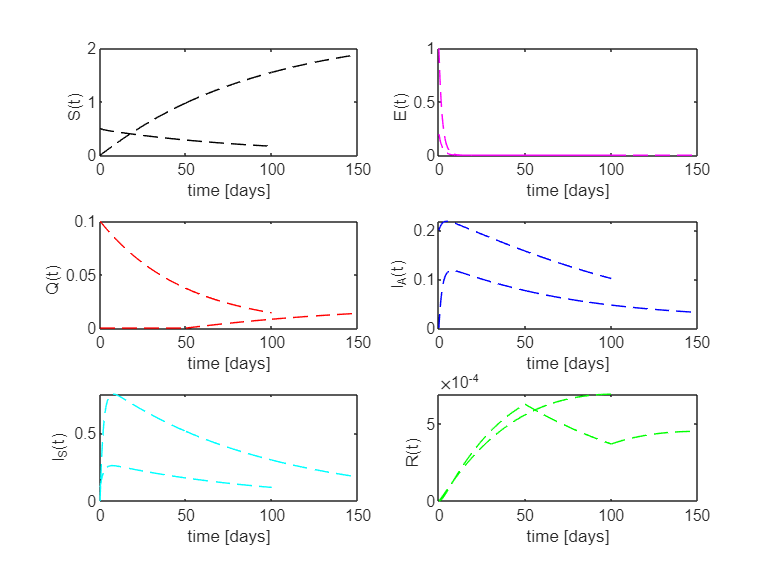

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,100], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

- **Estudia el impacto de otros parámetros en la evolución de la enfermedad.**

Realiza modificaciones en los valores de los parámetros para considerar distintas opciones de tasas de recuperación y distintos valores del número básico  de reproducción para analizar su impacto en la la evolución de la enfermedad.

Conviene recordar la notación. 

Para cada instante de tiempo $t$, la población total, $N(t)$, se compone de individuos

- susceptibles de infectarse, $S(t)$,

- ya expuestos al virus en dicho instante , $E(t)$,

- ya infectados y asintomáticos, $I_A(t)$,

- ya infectados y sintomáticos, $I_S(t)$,

- en cuarentena, $Q(t)$,

- recuperados o fallecidos, $R(t)$.

Para la evolución de las variables anteriores consideramos los parámetros:

- tasa de natalidad por unidad de tiempo, $\Lambda$,

- tasa de mortalidad natural, $\mu$,

- tasa de mortalidad entre sintomáticos, $\delta$ (suponemos nula la mortalidad entre asintomáticos),

- porcentaje de recuperados de entre los asintomáticos por unidad de tiempo, $r_1$ (resp. sintomáticos, $r_2$),

- porcentaje de susceptibles que van a cuarentena, $\tau$,

- porcentaje de contactos entre susceptibles y expuestos, i.e., *ratio de transmisión o de contacto efectivo*, $\beta$,

- porcentaje de expuestos que van a cuarentena, $\gamma$,

- porcentaje de expuestos que pasan a infectados sintomáticos, $\eta$ (resp. asintomáticos, $\sigma$),

- porcentaje de individuos en cuarentena que pasan a infectados sintomáticos, $\upsilon$ (resp. asintomáticos, $\theta$),

%Solucion

% Caso original del paper.
clf

P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 0.2, 0.1, 0.2, 0.1, 0);

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


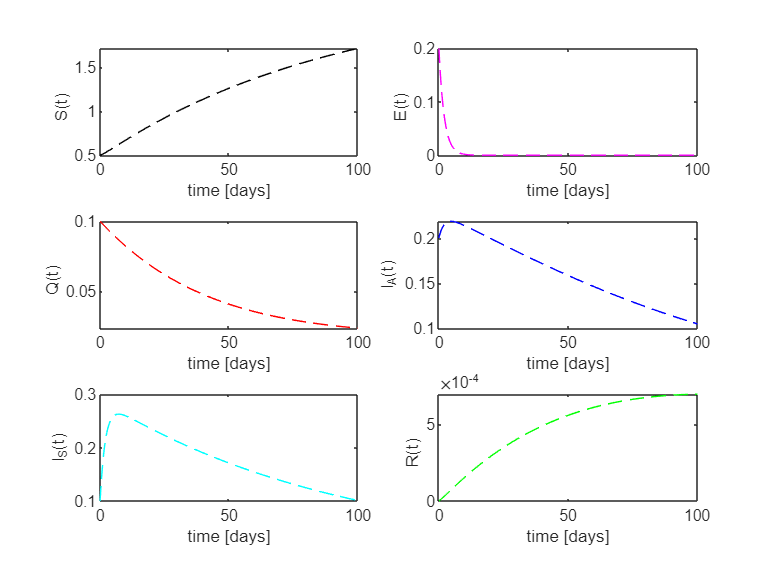

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,100], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

% Comenzamos aumentando r1 y r2: veamos que ocurre si es más fácil curarse
clf

P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 0.2, 0.1, 0.2, 0.1, 0);

P.r1 = 5.7341e-2;
P.r2 = 1.6728e-2;

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


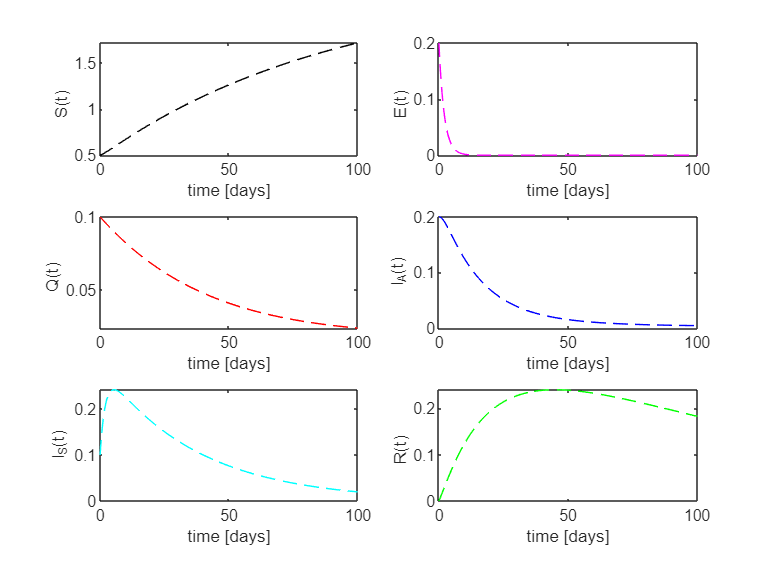

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,100], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

% Ahora disminuyendo r1 y r2: es más difícil curarse
clf

P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 0.15, 0.1, 0.15, 0.1, 0);

P.r1 = 5.7341e-15;
P.r2 = 1.6728e-15;

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


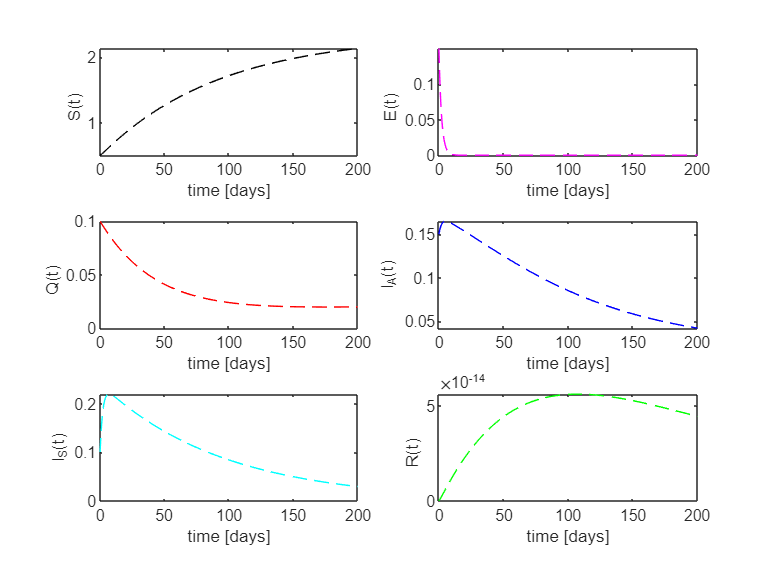

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,200], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

% Ahora gamma = 0: no hay cuarentenas
clf

P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 1, 0.1, 0.2, 0.1, 0);

P.gamma = 0;
P.tau = 0;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(0.5, 1, 0, 0.2, 0.1, 0);

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.36685 dias^(-1).


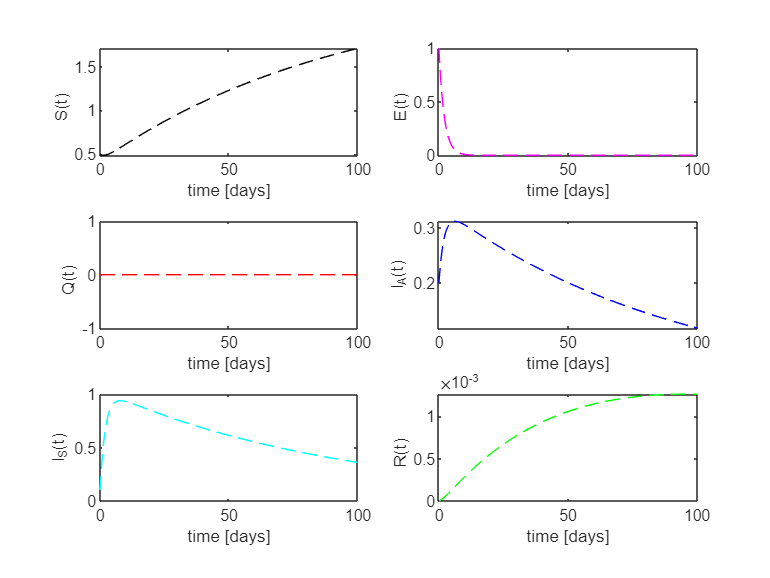

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,100], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

% La pandemia, desde el comienzo. Solo la etapa sin cuarentenas.
clf

P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(1, 1, 0, 0, 0, 0);

P  = struct('tau', 0.0002, 'beta', 0.0805, 'delta', 1.6728e-5, 'gamma', 2.0138e-4, ...
    'eta', 0.4478, 'tita', 0.0101, 'mu', 0.0106, 'nu', 3.2084e-4, 'sigma', 0.0668, ...
    'Lambda', 0.02537, 'r1', 5.7341e-5, 'r2', 1.6728e-5);
P.delta = 1.6728e-2;
P.nu = 3.2084e-4;
P.sigma = 0.0868;
P.gamma = 0;
P.tau = 0;
P.r1 = 5.7341e-15;
P.r2 = 1.6728e-15;

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35339 dias^(-1).


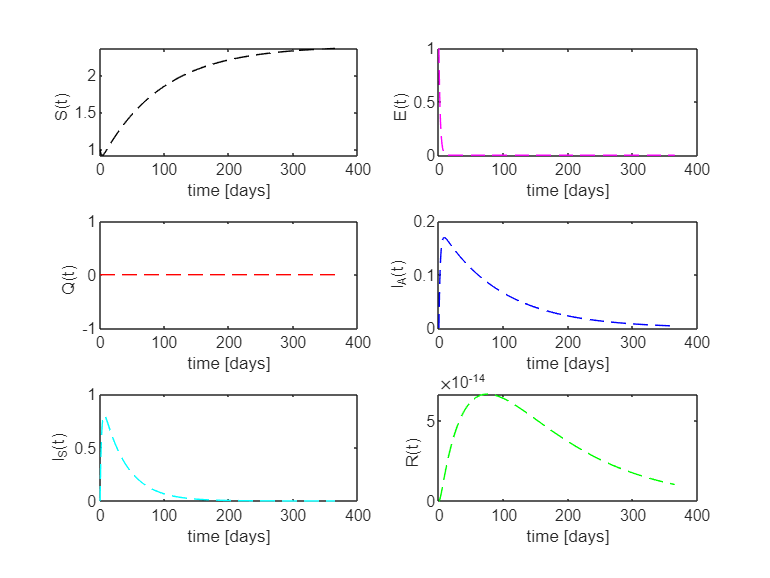

[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,365], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
end

Recordamos. Para cada instante de tiempo $t$, la población total, $N(t)$, se compone de individuos

- susceptibles de infectarse, $S(t)$,

- ya expuestos al virus en dicho instante , $E(t)$,

- ya infectados y asintomáticos, $I_A(t)$,

- ya infectados y sintomáticos, $I_S(t)$,

- en cuarentena, $Q(t)$,

- recuperados o fallecidos, $R(t)$.

Para la evolución de las variables anteriores consideramos los parámetros:

- tasa de natalidad por unidad de tiempo, $\Lambda$,

- tasa de mortalidad natural, $\mu$,

- tasa de mortalidad entre sintomáticos, $\delta$ (suponemos nula la mortalidad entre asintomáticos),

- porcentaje de recuperados de entre los asintomáticos por unidad de tiempo, $r_1$ (resp. sintomáticos, $r_2$),

- porcentaje de susceptibles que van a cuarentena, $\tau$,

- porcentaje de contactos entre susceptibles y expuestos, i.e., *ratio de transmisión o de contacto efectivo*, $\beta$,

- porcentaje de expuestos que van a cuarentena, $\gamma$,

- porcentaje de expuestos que pasan a infectados sintomáticos, $\eta$ (resp. asintomáticos, $\sigma$),

- porcentaje de individuos en cuarentena que pasan a infectados sintomáticos, $\upsilon$ (resp. asintomáticos, $\theta$),

% La pandemia, desde el comienzo. Sin cuarentenas. De repente entra la
% cuarentena. De repente entra la vacuna.
clf

% Covid entra inadvertido. No hay cuarentena.
P = Q;
[S0,  E0,  Q0,  IA0, IS0, R0] = deal(1, 1, 0, 0, 0, 0);

P  = struct('tau', 0, ...
            'beta', 0.0805, ...
            'delta', 1.6728e-5, ...
            'gamma', 0, ...
            'eta', 0.4478, ...
            'tita', 0.0101, ...
            'mu', 0.0106, ...
            'nu', 3.2084e-4, ...
            'sigma', 0.0668, ...
            'Lambda', 0.02537, ...
            'r1', 5.7341e-5, ...
            'r2', 1.6728e-5);

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.36685 dias^(-1).


[t, y] = ode45(@(t,y) odefcn(t,y,P), [0,50], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
    hold on
end


% Primeras medidas: cuarentena total.
[S0,E0,Q0,IA0,IS0,R0] = deal(y(end,1),y(end,2),y(end,3),y(end,4),y(end,5),y(end,6));

P  = struct('tau', 0.0002, ...
            'beta', 0.0805, ...
            'delta', 1.6728e-5, ...
            'gamma', 2.0138e-4, ...
            'eta', 0.4478, ...
            'tita', 0.0101, ...
            'mu', 0.0106, ...
            'nu', 3.2084e-4, ...
            'sigma', 0.0668, ...
            'Lambda', 0.02537, ...
            'r1', 0, ...
            'r2', 0);

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


[t, y] = ode45(@(t,y) odefcn(t,y,P), [t(end),t(end)+50], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
    hold on
end

% Siguientes medidas: se relaja la cuarentena y llega la vacuna.
[S0,E0,Q0,IA0,IS0,R0] = deal(y(end,1),y(end,2),y(end,3),y(end,4),y(end,5),y(end,6));

P  = struct('tau', 0.0002, ...
            'beta', 0.0805, ...
            'delta', 1.6728e-15, ...
            'gamma', 2.0138e-4, ...
            'eta', 0.4478, ...
            'tita', 0.0101, ...
            'mu', 0.0106, ...
            'nu', 3.2084e-4, ...
            'sigma', 0.0668, ...
            'Lambda', 0.02537, ...
            'r1', 5.7341e-5, ...
            'r2', 1.6728e-5);

R_0 = P.beta*P.Lambda / ((P.gamma+P.mu+P.eta+P.sigma)*(P.tau+P.mu));
disp(['Numero basico de reproduccion: ' num2str(R_0) ' dias^(-1).'])

Numero basico de reproduccion: 0.35992 dias^(-1).


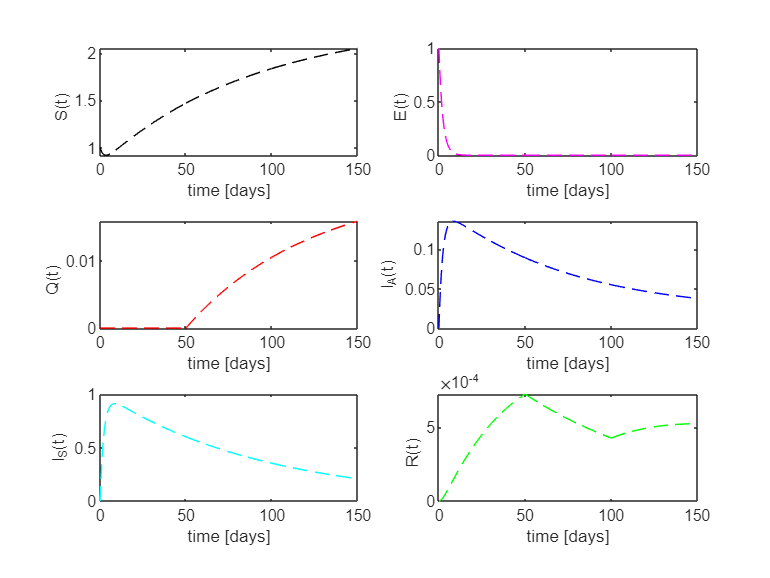

[t, y] = ode45(@(t,y) odefcn(t,y,P), [t(end),t(end)+50], [S0,E0,Q0,IA0,IS0,R0], odeset('RelTol',1e-7));
color = 'kmrbcg';
ylbl  = ['S(t)  '; 'E(t)  '; 'Q(t)  '; 'I_A(t)'; 'I_S(t)'; 'R(t)  '];
for i=1:6
    subplot(3,2,i)
    plot(t, y(:,i), [color(i) '--'])
    ylabel(ylbl(i,:))
    xlabel('time [days]')
    hold on
end

## **Anexo. Funciones utilizadas en esta práctica**

En Matlab, las funciones utilizadas en un *script*, van al final de éste.

function dydt = odefcn(t, y, P)
  % DYDT   Modelo SEQIR evolucion COVID-19.
  dydt = zeros(6,1);
  dydt(1) = P.Lambda-(P.tau+P.mu)*y(1) - P.beta*y(1)*y(2);
  dydt(2) = P.beta*y(1)*y(2) - (P.gamma+P.mu+P.eta+P.sigma)*y(2);
  dydt(3) = P.tau*y(1) + P.gamma*y(2) - (P.mu+P.nu+P.tita)*y(3);
  dydt(4) = P.sigma*y(2) + P.tita*y(3) - (P.mu+P.r1)*y(4);
  dydt(5) = P.eta*y(2) + P.nu*y(3) - (P.delta+P.mu+P.r2)*y(5);
  dydt(6) = P.r1*y(4) + P.r2*y(5) - P.mu*y(6);
end